# HW03

## Problem 4:

## Behavior of $\theta(t)$after a long time for different initial conditions:

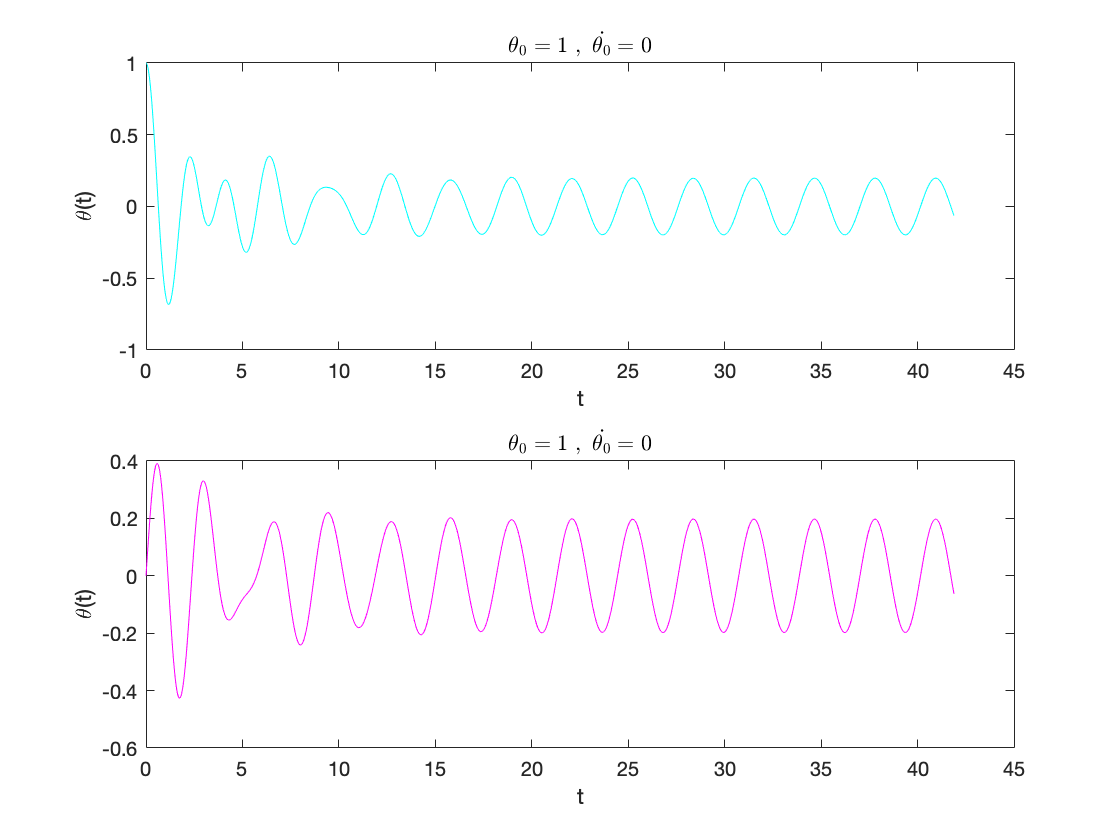

[T1,sol1]=forced_pendulum(1.09, 1,0,0,0.5,2);

[T2,sol2]=forced_pendulum(1.09, 0,1,0,0.5,2);

f1=figure;

subplot(2,1,1)
plot (sol1(:,1),sol1(:,2), 'c');
title('$\theta_0=1 \ , \ \dot{\theta_0}=0$', 'Interpreter','latex')
xlabel('t')
ylabel('\theta(t)')


subplot(2,1,2)
plot (sol2(:,1),sol2(:,2), 'm');
title('$\theta_0=1 \ , \ \dot{\theta_0}=0$', 'Interpreter','latex')
xlabel('t')
ylabel('\theta(t)')



fprintf('******************************** \n T1 = %f , w = %f  \n T2 = %f , w = %f \n******************************** ' , T1,6.28 ./ T1,T2 , 6.28 ./ T2);

******************************** 
 T1 = 3.134534 , w = 2.003488  
 T2 = 3.142017 , w = 1.998716 
******************************** 

## Behavior of $\theta(t)$ for different frequency of the external force :

frequency $\omega$ determines the period of the steady state.

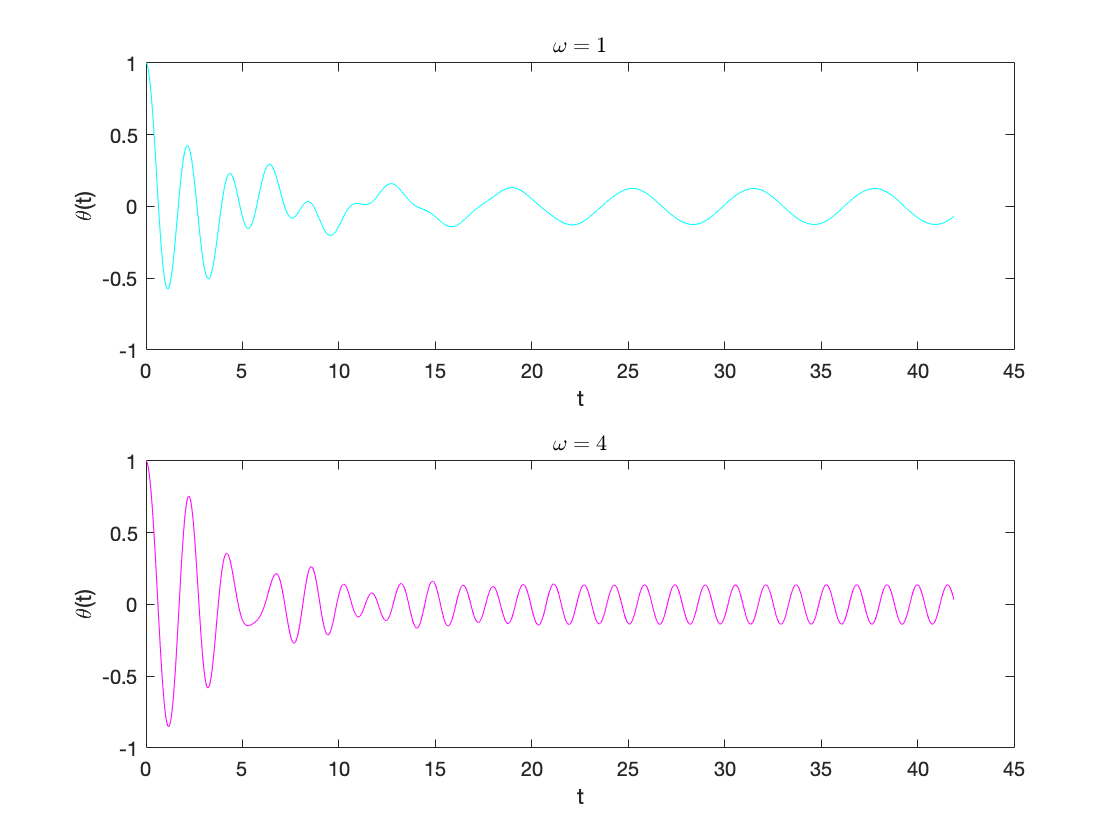

[T1,sol1]=forced_pendulum(1.09, 1,0,0,0.5,1);
[T2,sol2]=forced_pendulum(1.09, 1,0,0,0.5,4);

f2=figure;

subplot(2,1,1)
plot (sol1(:,1),sol1(:,2), 'c');
title('$\omega = 1$', 'Interpreter','latex')
xlabel('t')
ylabel('\theta(t)')


subplot(2,1,2)
plot (sol2(:,1),sol2(:,2), 'm');
title('$\omega =4$', 'Interpreter','latex')
xlabel('t')
ylabel('\theta(t)')



fprintf('******************************** \n T1 = %f , w = %f  \n T2 = %f , w = %f \n******************************** ' , T1,6.28 ./ T1,T2 , 6.28 ./ T2);

******************************** 
 T1 = 5.372514 , w = 1.168913  
 T2 = 1.573035 , w = 3.992283 
******************************** 

## Verifying the following equation:


$$\theta(t) = A(\omega)\cos(\omega t + \delta) $$



$$\delta = \cos ^{-1}(\frac{\theta}{A})-\omega t$$


For $\omega=2$ we have :

clear max;
w=2; % frequency of the driven force
[T,sol]=forced_pendulum(1.09, 1,0,0,0.5,2);
l=length(sol(:,1)) ;
l=int16(l/2);% using the second half of the data which represents the steady state
M=sol(end-l:end,2);
A =max(M); % amplitude
delta=acos(sol(end-l:end,2)/A)-w*mod((sol(end-l:end,1)),T) % phase shift

delta =   -0.2850 + 0.0000i
  -0.2809 + 0.0000i
  -0.2771 + 0.0000i
  -0.2734 + 0.0000i
  -0.2700 + 0.0000i
  -0.2666 + 0.0000i
  -0.2634 + 0.0000i
  -0.2603 + 0.0000i
  -0.2573 + 0.0000i
  -0.2544 + 0.0000i
  -0.2514 + 0.0000i
  -0.2478 + 0.0000i
  -0.2435 + 0.0000i
  -0.2379 + 0.0000i
  -0.2294 + 0.0000i
  -0.2104 + 0.0000i
  -0.1744 - 0.0920i
  -0.2743 - 0.1208i
  -0.3741 - 0.0258i
  -0.6566 + 0.0000i
  -0.8695 + 0.0000i
  -1.0755 + 0.0000i
  -1.2788 + 0.0000i
  -1.4573 + 0.0000i
  -1.6352 + 0.0000i
  -1.8127 + 0.0000i
  -1.9898 + 0.0000i
  -2.1667 + 0.0000i
  -2.3434 + 0.0000i
  -2.5467 + 0.0000i
  -2.7499 + 0.0000i
  -2.9528 + 0.0000i
  -3.1555 + 0.0000i
  -3.3581 + 0.0000i
  -3.5604 + 0.0000i
  -3.7814 + 0.0000i
  -4.0021 + 0.0000i
  -4.2224 + 0.0000i
  -4.4422 + 0.0000i
  -4.6615 + 0.0000i
  -4.8802 + 0.0000i
  -5.0939 + 0.0000i
  -5.3066 + 0.0000i
  -5.5175 + 0.0000i
  -5.7254 + 0.0000i
  -5.9280 + 0.0000i
   0.1493 + 0.0000i
  -0.0117 + 0.0000i
  -0.1287 + 0.0000i
  -0.1939 + 

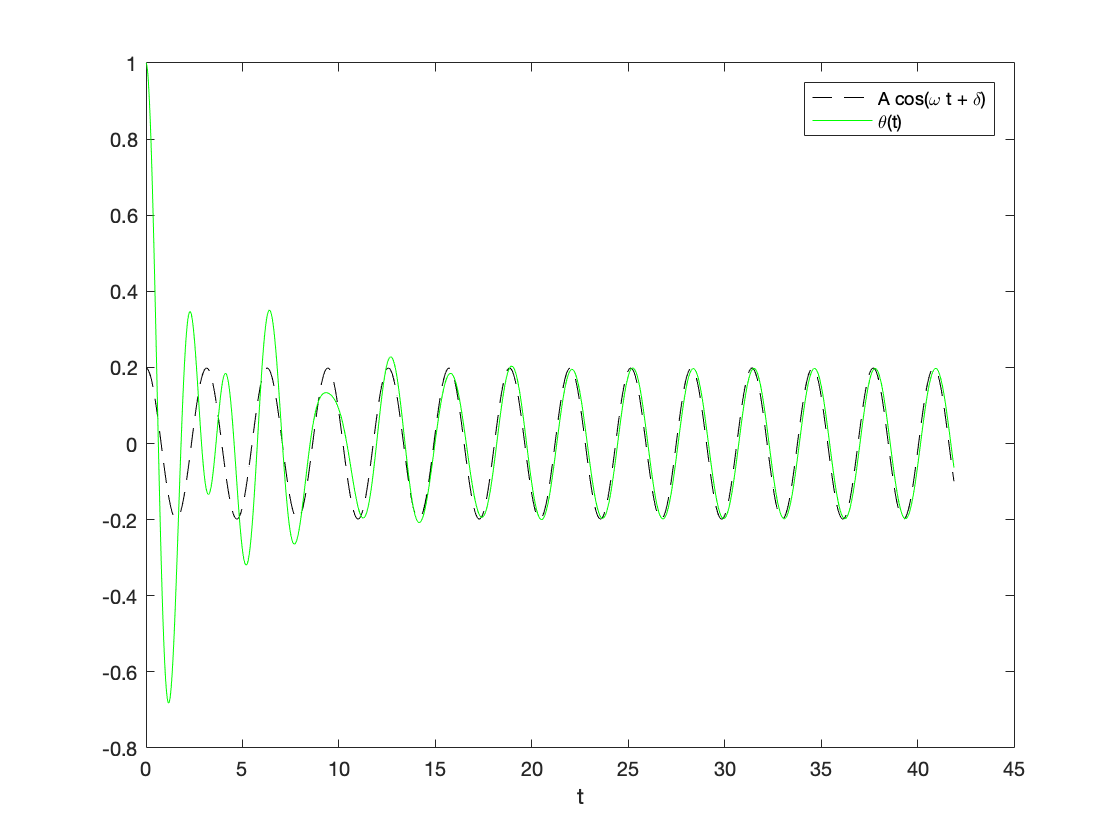


delta=min(delta);

y=A .* cos(w .* sol(:,1) + 6.28 *delta);

f3=figure;
plot(sol(:,1),y, 'k--', sol(:,1),sol(:,2),'g')
legend('A cos(\omega t + \delta) ','\theta(t)')
xlabel('t');

## Dependence of $\delta $on $\omega$:

gamma=0.5; % damping coefficient
w=[0, 1.0, 2.0, 2.2, 2.4, 2.6, 2.8, 3.0, 3.2, 3.4];
delta1=zeros(length(w),1);
for i=1:length(w)
   [T,sol]=forced_pendulum(1.09, 1,0,0,gamma,w(i)); 
   
   l=length(sol(:,1)) ;
   l=int16(l/2);% using the second half of the data which represents the steady state
   M=sol(end-l:end,2);
   A =max(M); % amplitude
   delta=acos(sol(end-l:end,2)/A)-w(i)*mod((sol(end-l:end,1)),T); % phase shift

   delta1(i)=mean(delta);
   

   
end    

gamma=1.5; % damping coefficient
w=[0, 1.0, 2.0, 2.2, 2.4, 2.6, 2.8, 3.0, 3.2, 3.4];
delta2=zeros(length(w),1);
for i=1:length(w)
   [T,sol]=forced_pendulum(1.09, 1,0,0,gamma,w(i)); 
   
   l=length(sol(:,1)) ;
   l=int16(l/2);% using the second half of the data which represents the steady state
   M=sol(end-l:end,2);
   A =max(M); % amplitude
   delta=acos(sol(end-l:end,2)/A)-w(i)*mod((sol(end-l:end,1)),T); % phase shift

   delta2(i)=mean(delta);

end    

f4=figure;
subplot(2,1,1)
plot(w,delta1);

title('\gamma = 0.5')
xlabel('\omega');
ylabel('\delta');


subplot(2,1,2)
plot(w,delta2);

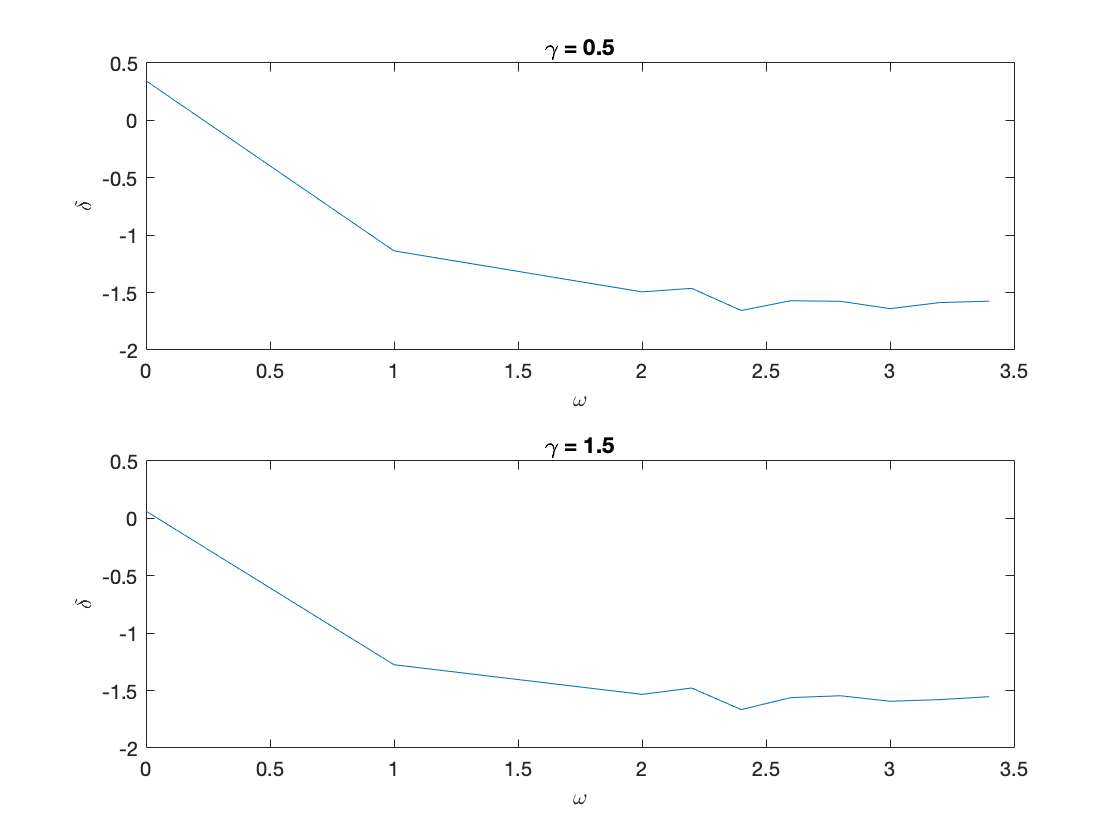

title('\gamma = 1.5')
xlabel('\omega');
ylabel('\delta');

## Resonance:

Maximum amplitude occures at $\omega_{max} <\omega_0=3$ for $\gamma=0.5$.

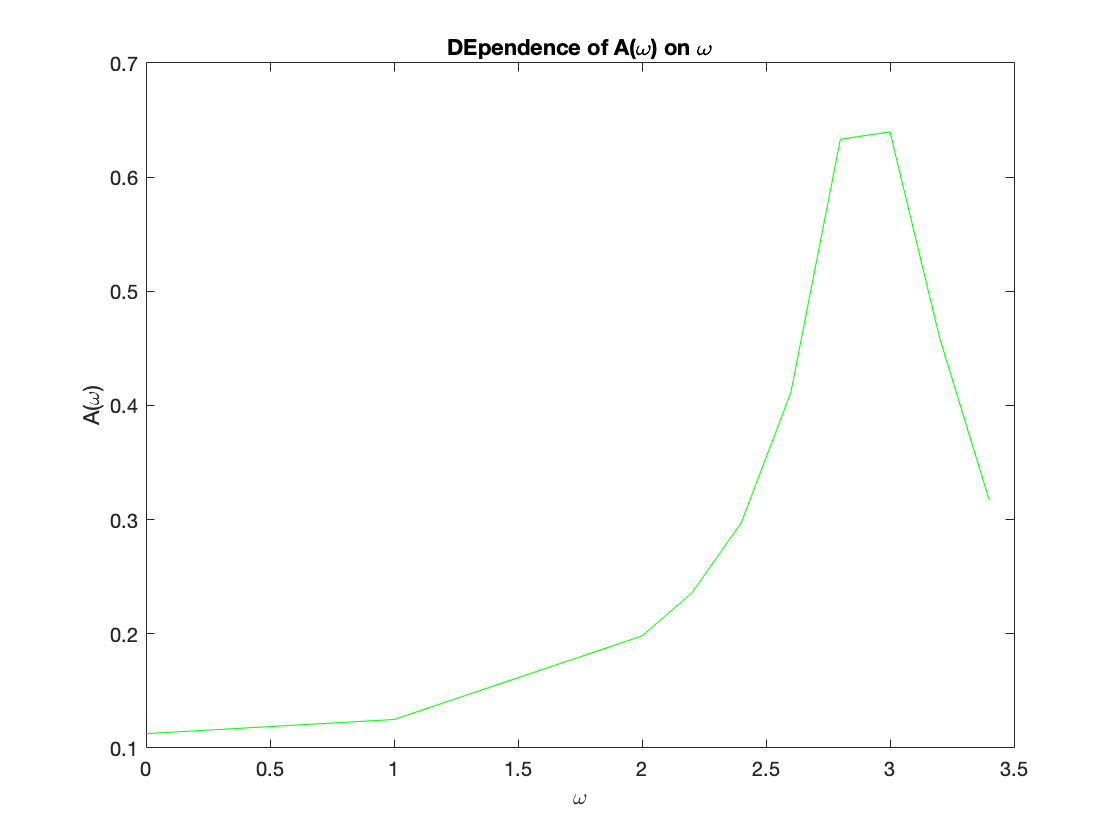

clear max;
gamma=0.5; % damping coefficient
w=[0, 1.0, 2.0, 2.2, 2.4, 2.6, 2.8, 3.0, 3.2, 3.4];
A=zeros(length(w),1);
for i=1:length(w)
   [T,sol]=forced_pendulum(1.09, 0,0,0,gamma,w(i)); 
   l=length(sol(:,1)) ;
   l=int16(l/2);% using the second half of the data which represents the steady state
   M=sol(end-l:end,2);
   A(i) = max(M);
   
end    

f5=figure;
plot(w,A,'g');
title('DEpendence of A(\omega) on \omega');
xlabel('\omega');
ylabel('A(\omega)');

[Amax,ind]=max(A); 
wmax=w(ind);
ind1=0;
ind2=0;
for i=1:length(w)
    if A(i) <= (1 ./ sqrt(2)) * Amax && w(i) < wmax
        ind1=i;
    end
    
    if A(i) <= (1 ./ sqrt(2)) * Amax && w(i) > wmax
        ind2=i;
    end
end    

delta_w=w(ind2)-w(ind1);
fprintf('**************************** \n A_max = %f \n w_max = %f \n delta_w = %f \n****************************\n', Amax , wmax,delta_w);

**************************** 
 A_max = 0.639660 
 w_max = 3.000000 
 delta_w = 0.800000 
****************************


## Dependence of $A_{max}$ and $\frac{\Delta\omega}{\omega_{max}}$ on $\gamma$:

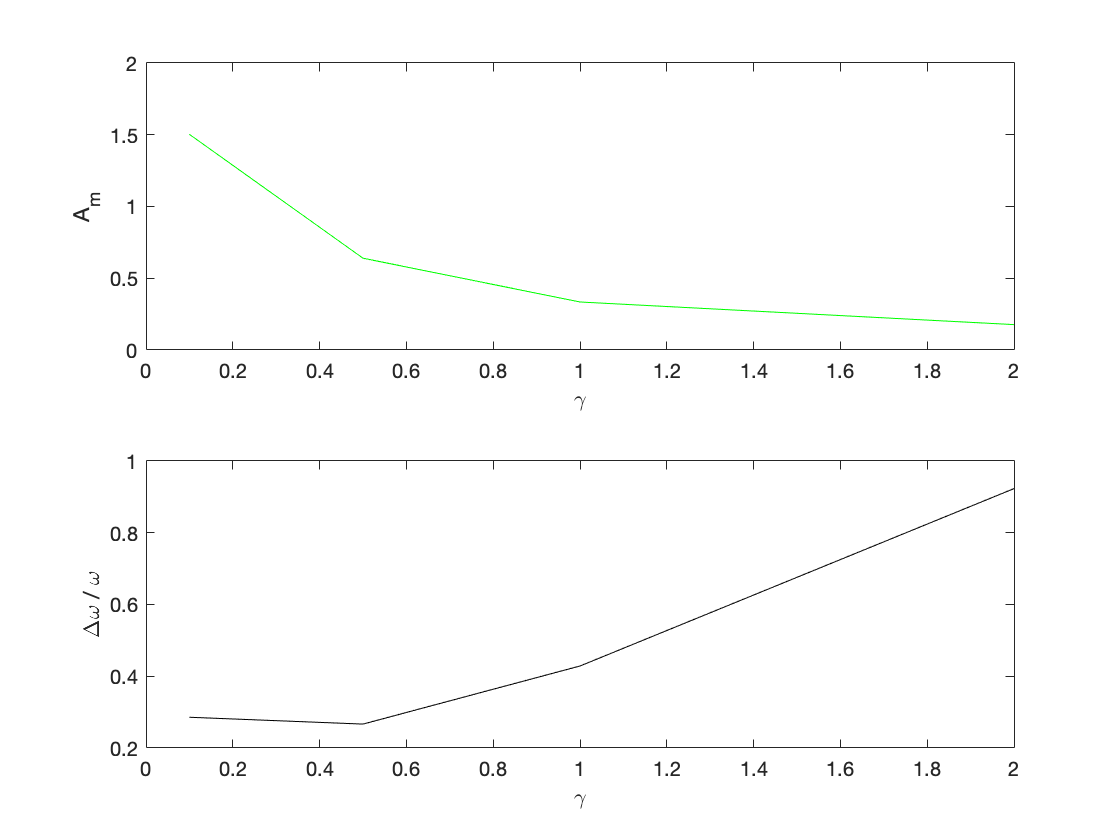

clear max;
gamma=[0.1, 0.5, 1.0, 2.0];
w=[0, 1.0, 2.0, 2.2, 2.4, 2.6, 2.8, 3.0, 3.2, 3.4];
Amax=zeros(length(gamma),1);
wmax=zeros(length(gamma),1);
delta_w=zeros(length(gamma),1);

for j=1:length(gamma)
    A=zeros(length(w),1);
    for i=1:length(w)
        
        [T,sol]=forced_pendulum(1.09, 0,0,0,gamma(j),w(i)); 
        l=length(sol(:,1)) ;
        l=int16(l/2);% using the second half of the data which represents the steady state
        M=sol(end-l:end,2);
        A(i) = max(M);
      
    end    
     [Amax(j),ind]=max(A); 
      wmax(j)=w(ind);
      for k=1:length(w)
           if (A(k) <= (1 ./ sqrt(2)) * Amax(j)) && (w(k) < wmax(j))
               ind1=k;
           end
    
          if A(k) <= (1 ./ sqrt(2)) * Amax(j) && w(k) > wmax(j)
               ind2=k;
          end
      end    

     delta_w(j)=w(ind2)-w(ind1);
     
    
       
end   

ratio=delta_w ./ wmax;
f6=figure;
subplot(2,1,1)
plot(gamma,Amax,'g')
xlabel('\gamma')
ylabel('A_m')

subplot(2,1,2)
plot(gamma,ratio,'k')
xlabel('\gamma')
ylabel('\Delta\omega / \omega')